
if false
image = imread('D:\Skola\ABoB\TNM034-OMR\Images\TestStaff.jpg');
imshow(image)

binaryImage = im2bw(image,0.7);
imshow(binaryImage)

verticalProfile = sum(binaryImage, 2);
[rows, columns] = size(binaryImage);
stem(columns-verticalProfile)
hold off


imageVector = im2double(verticalProfile);
[pks,locs] = findpeaks((columns-imageVector)); 
stem(locs,pks);



maxValue_Peaks = max(pks);
staffs = pks .* (pks > maxValue_Peaks*0.9);
hold off 
stem(locs,staffs)
end

%create an array containing the rows where the stafflines are located (staffRows)
if false 
j = locs(:) < staffs(:);
staffRows = j.*locs;
staffRows(staffRows==0) = [];  
end

% check if stafflines has a width larger than one row and ads those row to staffRows
% so that they can be removed later 
if false 
a = [];
b = [];

v = columns-imageVector; 
for i = 1:length(staffRows)
    if(v(staffRows(i)-1) > 500) % 500 bör ändras till något som inte är så hårdkodat
   
       a = [a,staffRows(i)-1];
    end
    if(v(staffRows(i)+1) > 500)

       b = [b,staffRows(i)+1];
    end
end 
c = [a,b];

staffRows = staffRows';
staffRows = [staffRows,c];
end

%remove the stafflines      
if false 
removed_Stafflines_image = binaryImage;
removed_Stafflines_image(staffRows(:),:) = 1; %must rewrite what if width is >1 row??? 
imshow(removed_Stafflines_image)
title('Min "fina" lösning')
end

%% remove almost all staffline. keep notes intact.
%koden funkar men förlorar små punkter som innehåller viktig information 
%imsubtractz
if false 
notes = loadimage('D:\Skola\ABoB\TNM034-OMR\Images\TestStaff.jpg');
verticals = imclose(notes, strel('Line',4,90));
horizontals = imclose(notes, strel('Line',150,0));
subtracted = 1-imsubtract(verticals, horizontals);
disc =imclose(notes, strel('disk',2,4));
imshow(verticals)
title('Verticals')
imshow(disc>0.8)
title('disc > 0.8')
%imshow(horizontals)
%imshow(subtracted)
%imshow(subtracted>0.9)
result = (1-notes).*(subtracted>0.9);
super =(1-result).*(disc>0.8);
superverticals = imclose(notes, strel('Line',4,90));
imshow(superverticals);
title('superverticals')
%imshow((1-result).*(disc>0.8))
imshow(verticals.*(disc>0.7))
title('verticals.*(disc>0.8)')
end

%The excellent solution 
%min lösning för att ta bort staffline, verticals för att bli av med stödlinjerna, 
if false 
po = verticals.*(disc>0.7);
se = strel('cube',1);
eroded = imerode(po, se);
imshow(eroded>0.9)
title('eroded')

end 

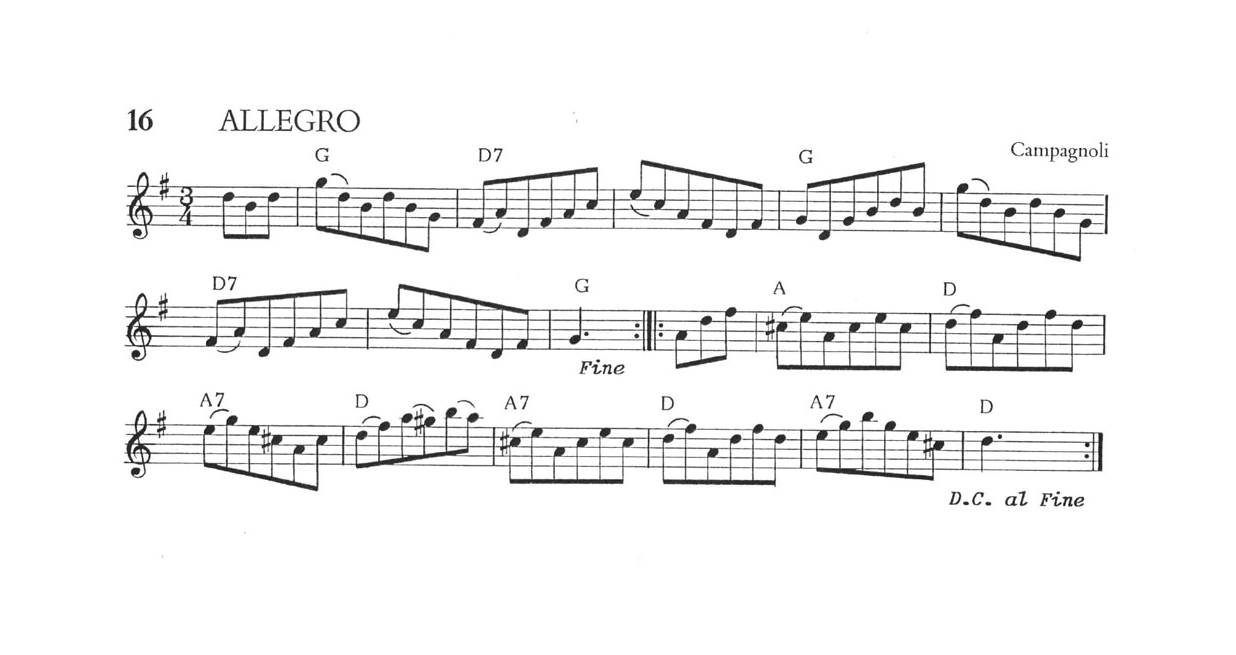

image = imread('D:\Skola\ABoB\TNM034-OMR\Images\Im5s.jpg');
imshow(image)

verticals = imclose(image, strel('Line',4,90));

disc =imclose(image, strel('disk',2,4));

moreContrastVerticals = verticals.*(disc>0.7);

Error using  .* 
Integers can only be combined with integers of the same class, or scalar doubles.

se = strel('cube',1);


noStaffImage = imerode(moreContrastVerticals, se);
noStaffImage = noStaffImage > 0.9;
imshow(noStaffImage)

result = cat(2,image,noStaffImage);
montage(result);


image = imread('D:\Skola\ABoB\TNM034-OMR\Images\Im5s.jpg');
verticals = image < graythresh(image);
verticals = imclose(verticals, strel('Line',4,90));

disc =imclose(verticals, strel('disk',2,4));

moreContrastVerticals = verticals.*(disc>0.7);
se = strel('cube',1);


noStaffImage = imerode(moreContrastVerticals, se);
noStaffImage = noStaffImage > 0.9;

